# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 11

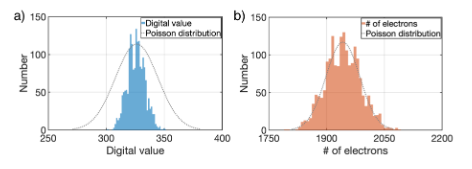

Fig. 11. (a) Histogram of measured digital values. The mean is equal to 320.7 and the variance is equal to 57.8. (b) After scaling by the inverse of the conversion gain we can obtain an estimate of the number of electrons. In this case, the distribution mean and variance are more nearly equal as expected in Equation (6). This is consistent with the expected Poisson character of the light.

### Read the digital values from Pixel 4a files

We read multiple images of the digital values into the cell array.  We extract a region (10 x 10) from each of these images.  This produces a set of 1500 samples, taken from a small region so that the illumination is quite uniform.

% The scene is uniform, and we will only use a small part of it.
load('p4aLensVignet_dc_p55_pos1.mat', 'pixel4aLensVignetSlope');
vignetting = pixel4aLensVignetSlope;

% We need to remove the
expDuration = 10;   % In ms
nFrames = 15;       % Number of images we captured
nExp = numel(exposures);
intSphereDir = fullfile(cboxRootPath, 'data', 'measurement',...
                                      'integratingsphere',...
                                        'dc_p55_pos1');                                 

% We will store the digital values in this cell array
sensorImgs = cell(nFrames,1);

thisExpDir = fullfile(intSphereDir, num2str(expDuration));
thisExpDngs = dir(fullfile(thisExpDir, '*.dng'));
for jj = 1:nFrames
    [sensor, info] = sensorDNGRead(fullfile(thisExpDir, thisExpDngs(jj).name));
    sensorImgs{jj} = double(sensorGet(sensor, 'dv'));
end

#### Crop a central 10 x 10 region

cropWindow = [980 759 10 10];

offset = sensorGet(sensor, 'black level');
cropSensorImgs = [];
for ii=1:nFrames
    thisFrame = ii;
    % Take the window crop and correct with local PRNU
    thisG = sensorImgs{thisFrame}(2:2:end, 1:2:end)-offset;
    thisSensorData = thisG ./ imresize(vignetting, 0.5);
    thislocalWin = imcrop(thisSensorData, cropWindow);
    cropSensorImgs = [cropSensorImgs;thislocalWin]; %#ok<AGROW> 
end

### Compute the estimated conversion gain

We use the equations in the paper with the cropSensorImgs data to calculate the conversion gain.

thisMeanDV = mean(cropSensorImgs(:));
thisVarDV = var(cropSensorImgs(:));
sensorCB = cbSensorCreate;
prnu = sensorGet(sensorCB, 'prnu level')/100;
estCG = (thisVarDV-thisMeanDV^2*prnu^2)/thisMeanDV * (1+prnu^2); % (dv/e-)

vSwing = sensorGet(sensor, 'pixel voltage swing');
assumedCG = (sensorGet(sensor, 'pixel conversion gain') * 1024/vSwing);
ratio = estCG / assumedCG;
fprintf('Ratio: %.4f.\n', ratio);

Ratio: 0.9824.


fprintf('Relative error: %.4f percent \n', abs(estCG-assumedCG)/assumedCG*100);

Relative error: 1.7609 percent 


### Show the histograms compared to Poisson noise

#### First we compare the digital values

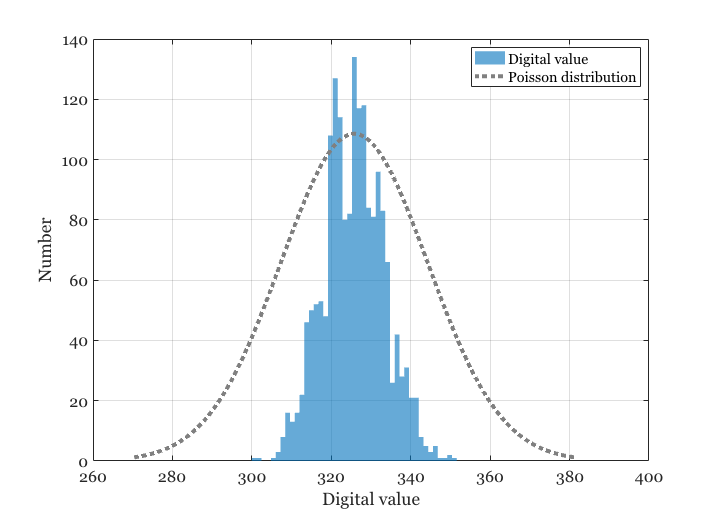

ieNewGraphWin; 
hold all;
% Measured data
histogram(cropSensorImgs(:), 50, 'BinLimits', [300 360],...
                'facecolor', [0 0.4470 0.7410],...
                'edgecolor', 'none');
% Poisson distribution in dv space
poisDV = poissrnd(mean(cropSensorImgs(:)), size(cropSensorImgs(:)));
hDV = histfit(poisDV);
hDV(2).Color = [0.5 0.5 0.5];
hDV(2).LineStyle = ':';
hDV(2).LineWidth = 4;
delete(hDV(1));
grid on; box on; xlabel('Digital value'); ylabel('Number');
xticks(260:20:400); xlim([260 400]);
legend('Digital value', 'Poisson distribution');

#### Next, we compare the estimated electron counts, after applying the conversion gain

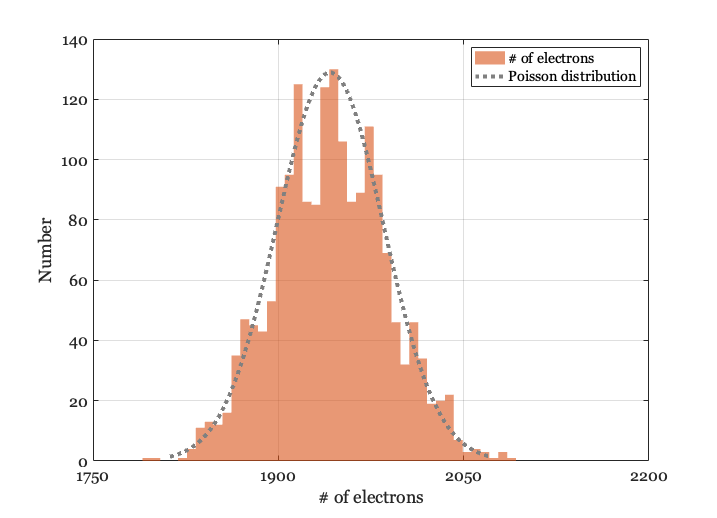

ieNewGraphWin;
hold all;
% Measured data
histogram(cropSensorImgs(:)/estCG, 50, 'BinLimits', uint32([300 360]/estCG/10)*10,...
                'facecolor', [0.8500 0.3250 0.0980],...
                'edgecolor', 'none');
% Poisson distribution in electron space
% Poisson distribution in dv space
poisE = poissrnd(mean(cropSensorImgs(:)/estCG), size(cropSensorImgs(:)));
hE = histfit(poisE);
hE(2).Color = [0.5 0.5 0.5];
hE(2).LineStyle = ':';
hE(2).LineWidth = 4;
delete(hE(1));
grid on; xlabel('# of electrons'); box on; ylabel('Number');
xticks(1750:150:2200); xlim([1750 2200]);
legend('# of electrons', 'Poisson distribution');